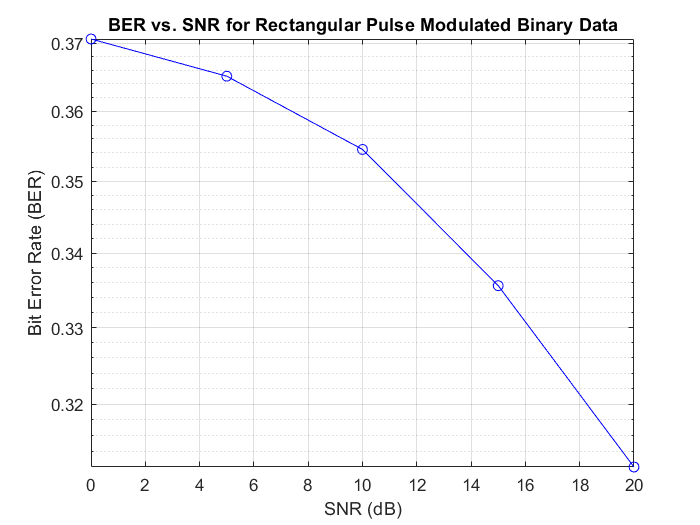

%simulation of binary baseband signals using a rectangular pulse and
%estimated the BER for AWGN
N=1e4;
SNR_dB =0:5:20;
pulse_width = 1;
data=randi([0 1], N, 1);
t=0:0.01:pulse_width;
rect_pulse= ones(size(t));
BER=zeros(length(SNR_dB), 1);
for snr_idx= 1:length(SNR_dB)
tx_signal = [];
for i=1:N
if data(i) == 1
tx_signal = [tx_signal; (rect_pulse')];
else
tx_signal= [tx_signal; zeros(size(rect_pulse'))];
end
end
SNR=10^(SNR_dB(snr_idx)/10);
noise_power = 1/(2* SNR);
noise = sqrt(noise_power) *randn(length(tx_signal), 1);
rx_signal=tx_signal + noise;
matched_filter = rect_pulse;
filtered_signal= conv(rx_signal, matched_filter, 'same');
sample_interval = round(length(filtered_signal)/N);
sampled_signal =filtered_signal(1:sample_interval:end);
estimated_bits =sampled_signal > 0.5;
num_errors = sum(estimated_bits ~= data);
BER(snr_idx) = num_errors / N;
end
figure;
semilogy(SNR_dB, BER, 'b-o');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs. SNR for Rectangular Pulse Modulated Binary Data');